# Predicting Loss in my Portfolio under Adverse Economic Conditions

Copyright (c) 2018, MathWorks, Inc.

The objective of this demo is to demonstrate a basic work flow for stress testing in banking portfolio.

## Get the portfolio of loans to test

Read in my portfolio from a spreadsheet

myPortfolio = readtable('OutstandingLoans.xlsx')

myPortfolio = 100×4 table
    RiskLevel    YOB    LGD      EAD  
    _________    ___    ____    ______

        1         1     0.25    21.627
        1         2     0.25    3.2595
        1         3     0.25    20.391
        1         4     0.25    3.7534
        1         5     0.25    5.7193
        1         6     0.25    5.9782
        1         7     0.25    13.775
        1         8     0.25    3.5679
        2         1     0.35    61.677
        2         2     0.35    47.608
        2         3     0.35    29.338
        2         4     0.35    4.8472
        2         5     0.35    14.764
        2         6     0.35    29.423
        2         7     0.35    18.903
        2         8     0.35    27.038


## Make a predictive model

Read in my historical loans and combine them with economic data from the Fed.

myLoanHistory   = readtable('OldLoans.xlsx')

myLoanHistory = 673931×5 table
    ID    RiskLevel    YOB    Year    Default
    __    _________    ___    ____    _______

    1         3         1     2006       0   
    1         3         2     2007       0   
    1         3         3     2008       0   
    1         3         4     2009       0   
    1         3         5     2010       0   
    1         3         6     2011       0   
    1         3         7     2012       0   
    1         3         8     2013       0   
    1         3         9     2014       0   
    1         3        10     2015       0   
    1         3        11     2016       0   
    1         3        12     2017       0   
    2         2         1     2006       0   
    2         2         2     2007       0   
    2         2         3     2008       0   
    2         2 

FedHistory      = readtable('Simplified_FedHistory.csv')

FedHistory = 18×3 table
    Year    DJX_Return      GDP   
    ____    __________    ________

    2000       5.9048       2.9106
    2001      -12.057      0.18959
    2002      -22.086       2.0429
    2003        29.45       4.3856
    2004       10.657       3.1236
    2005       4.5687       3.0212
    2006       13.755         2.41
    2007       3.7845       1.8436
    2008      -38.613      -2.7687
    2009       25.704     -0.23348
    2010       15.336        2.697
    2011     -0.85294       1.6742
    2012       13.949       1.2946
    2013       30.859       2.6683
    2014       10.364       2.6964
    2015      -1.5123       1.9947


combinedHistory = outerjoin(myLoanHistory,FedHistory,'Type','Left')

combinedHistory = 673931×8 table
    ID    RiskLevel    YOB    Year_myLoanHistory    Default    Year_FedHistory    DJX_Return    GDP 
    __    _________    ___    __________________    _______    _______________    __________    ____

     1        3         1            2006              0            2006            13.755      2.41
     2        2         1            2006              0            2006            13.755      2.41
     3        1         1            2006              0            2006            13.755      2.41
     4        3         1            2006              0            2006            13.755      2.41
     5        2         1            2006              0            2006            13.7

Create my predictive model from the combined historical data

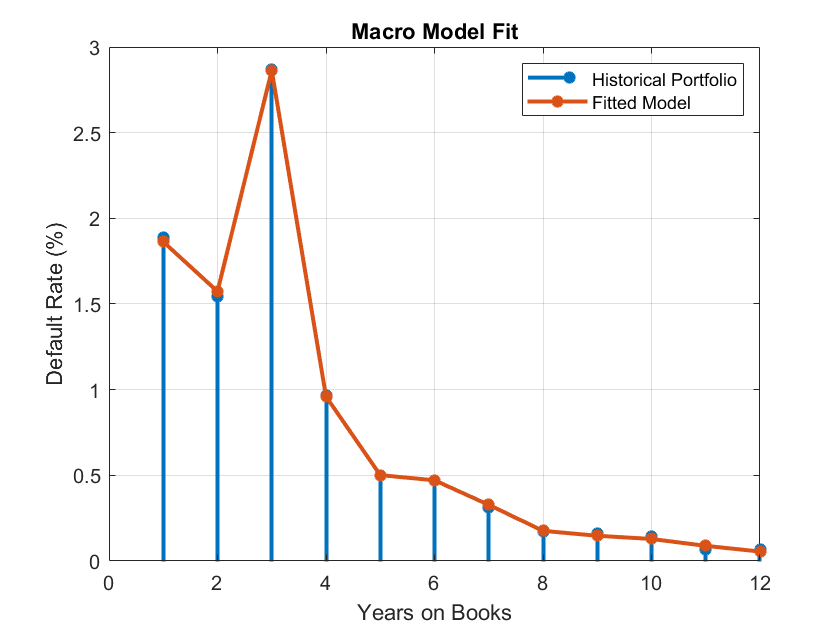

myModel = fitglm(combinedHistory, 'Distribution','binomial',...
    'PredictorVars',{'RiskLevel','YOB','DJX_Return','GDP'},'ResponseVar','Default');
showModelFit

## Predict the probability of default for each loan in my portfolio

AdverseScenario     = readtable('Simplified_Adverse.csv')

AdverseScenario = 3×3 table
    Year    DJX_Return      GDP  
    ____    __________    _______

    2018     -24.627      -2.1293
    2019      2.3588      0.79339
    2020      18.993       3.0748


myPortfolio.Year(:) = 2018;
AdversePortfolio    = outerjoin(myPortfolio,AdverseScenario(1,:),'Type','Left')

AdversePortfolio = 100×8 table
    RiskLevel    YOB    LGD      EAD      Year_myPortfolio    Year_right    DJX_Return      GDP  
    _________    ___    ____    ______    ________________    __________    __________    _______

        1         1     0.25    21.627          2018             2018        -24.627      -2.1293
        1         2     0.25    3.2595          2018             2018        -24.627      -2.1293
        1         3     0.25    20.391          2018             2018        -24.627      -2.1293
        1         4     0.25    3.7534          2018             2018        -24.627      -2.1293
        1         5     0.25    5.7193          2018             2018        -24.627      -2.1293
        1 

AdversePortfolio.PD = predict(myModel,AdversePortfolio)

AdversePortfolio = 100×9 table
    RiskLevel    YOB    LGD      EAD      Year_myPortfolio    Year_right    DJX_Return      GDP         PD    
    _________    ___    ____    ______    ________________    __________    __________    _______    _________

        1         1     0.25    21.627          2018             2018        -24.627      -2.1293     0.020211
        1         2     0.25    3.2595          2018             2018        -24.627      -2.1293     0.014833
        1         3     0.25    20.391          2018             2018        -24.627      -2.1293      0.01087
        1         4     0.25    3.7534          2018             2018        -24.627      -2.1293    0.0079

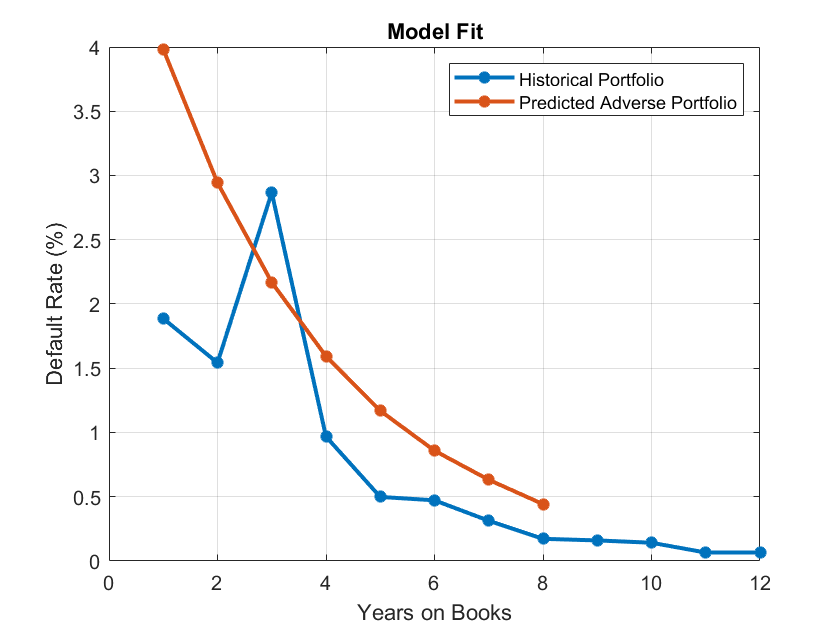

showPrediction

## Calculate the expected loss of my portfolio under adverse conditions

ExpectedLoss = sum(AdversePortfolio.EAD .* AdversePortfolio.PD .* AdversePortfolio.LGD)

ExpectedLoss = 23.2811